clear all 
close all 
clc

load('sujet1b.mat')

## observation des caractéristiques du signal

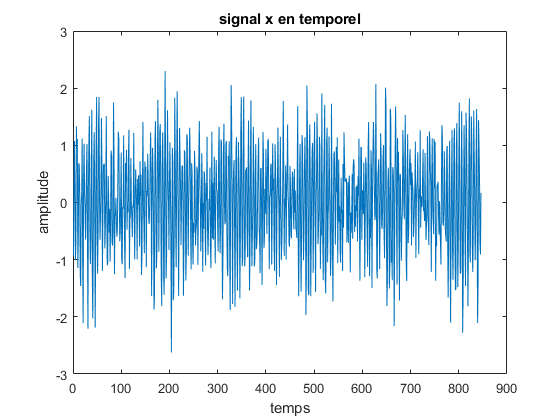

figure(1)
plot(x) ; xlabel('temps') ; ylabel('amplitude') ; title('signal x en temporel') ;


figure(2)
[modx,fx] = Spectre(x,fe,1)

modx =     0.0161    0.0107    0.0113    0.0153    0.0042    0.0103    0.0103    0.0106    0.0206    0.0200    0.0130    0.0017    0.0091    0.0235    0.0012    0.0118    0.0046    0.0093    0.0133    0.0156    0.0169    0.0085    0.0045    0.0092    0.0113    0.0152    0.0125    0.0066    0.0038    0.0208    0.0142    0.0091    0.0318    0.0170    0.0116    0.0073    0.0135    0.0200    0.0076    0.0239    0.0274    0.0329    0.0264    0.0175    0.0202    0.0129    0.0108    0.0153    0.0154    0.0142


fx =          0    1.8203    3.6407    5.4610    7.2813    9.1017   10.9220   12.7423   14.5626   16.3830   18.2033   20.0236   21.8440   23.6643   25.4846   27.3050   29.1253   30.9456   32.7660   34.5863   36.4066   38.2270   40.0473   41.8676   43.6879   45.5083   47.3286   49.1489   50.9693   52.7896   54.6099   56.4303   58.2506   60.0709   61.8913   63.7116   65.5319   67.3522   69.1726   70.9929   72.8132   74.6336   76.4539   78.2742   80.0946   81.9149   83.7352   85.5556   87.3759   89.1962


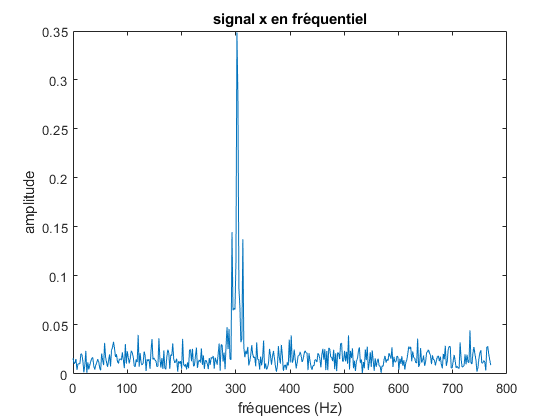

plot(fx,modx) ; xlabel('fréquences (Hz)') ; ylabel('amplitude') ; title('signal x en fréquentiel') ;

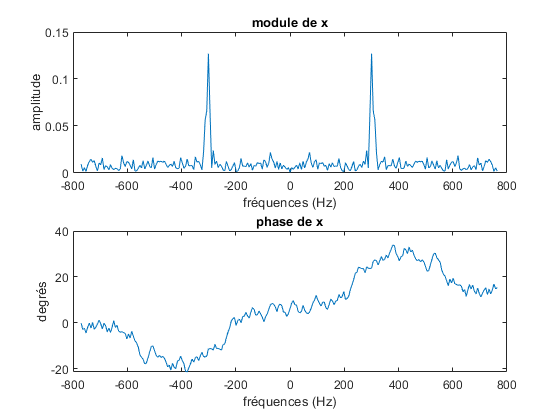


figure(3)
[Modulex, phasex, Fx] = DFTVisu(x,fe,256) ;
subplot(211) ; plot(Fx,Modulex) ;  xlabel('fréquences (Hz)') ; ylabel('amplitude') ; title('module de x') ;
subplot(212) ; plot(Fx, phasex) ;   xlabel('fréquences (Hz)') ; ylabel('degrés') ; title('phase de x') ;

## Débruitage à l'aide d'un filtre passe-bande

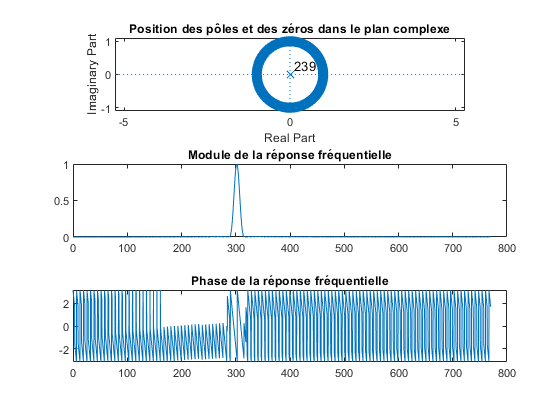

fo1=301;
fo2=303;
Deltaf=20;
lo1=fo1/fe;
lo2=fo2/fe;
DeltaFnorm1=Deltaf/fe;
M=round(3.1/DeltaFnorm1);
FHeb=fir1(M,2*[lo1 lo2]);

figure(4)
[Modf2,Phsf2,Ff2]=FilterVisu(FHeb,1,4096,fe);

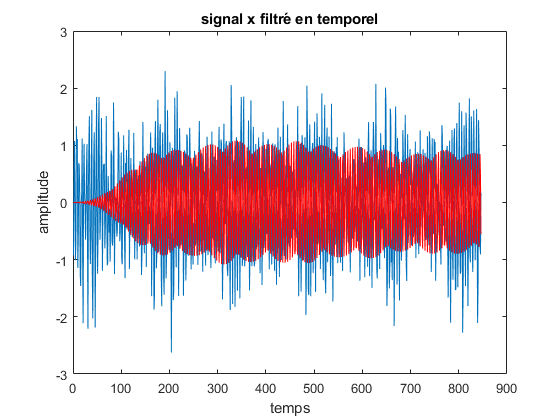

xHeb = filter(FHeb,1,x);

figure(5)
plot(x);
hold on;
plot(xHeb,'r');
xlabel('temps') ; ylabel('amplitude') ; title('signal x filtré en temporel')

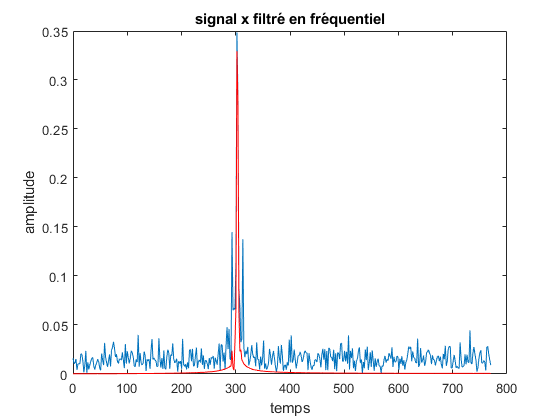


[ModHeb,FreqHeb]=Spectre(xHeb,fe,1);
figure(6)
plot(fx,modx);
hold on;
plot(FreqHeb,ModHeb,'r');
xlabel('temps') ; ylabel('amplitude') ; title('signal x filtré en fréquentiel')

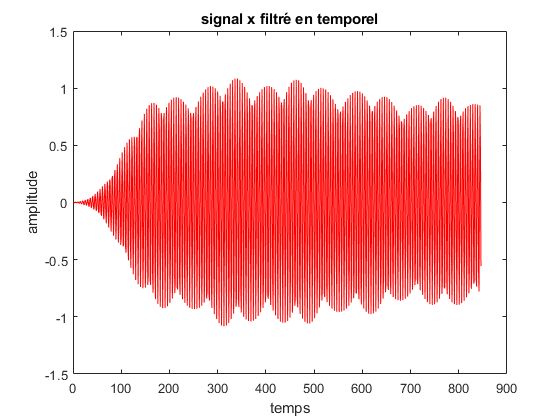

figure(7)
plot(xHeb,'r');
title('signal x filtré en temporel') ; xlabel('temps') ; ylabel('amplitude') ;